**Dataset Preparation**

# load Dataset

[data] = load_activity_data()

data = struct with fields:
           Sit: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
         Stand: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
          Walk: {{1×2 cell}  {1×2 cell}}
        Stairs: {1×32 cell}
          Bike: {{1×2 cell}  {1×2 cell}}
    Wheelchair: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
    Assessment: {{1×2 cell}}


# calculate Features

window_size=2 % set windowsize in seconds

window_size = 2

[Features] = calculate_features(data, window_size)

feature_count = 1

Features = struct with fields:
                Max_Accel_Right_x: [2273×1 double]
                Max_Accel_Right_y: [2273×1 double]
                Max_Accel_Right_z: [2273×1 double]
                 Max_Accel_Left_x: [2273×1 double]
                 Max_Accel_Left_y: [2273×1 double]
                 Max_Accel_Left_z: [2273×1 double]
                Min_Accel_Right_x: [2273×1 double]
                Min_Accel_Right_y: [2273×1 double]
                Min_Accel_Right_z: [2273×1 double]
                 Min_Accel_Left_x: [2273×1 double]
                 Min_Accel_Left_y: [2273×1 double]
                 Min_Accel_Left_z: [2273×1 double]
                Std_Accel_Right_x: [2273×1 double]
                Std_Accel_Right_y: [2273×1 double]
                Std_Accel_Right_z: [2273×1 double]
                 Std_Accel_Left_x: [2273×1 double]
                 Std_Accel_Left_y: [2273×1 double]
                 Std_Accel_Left_z: [2273×1 double]
       Mean_Mean_Accel_Left_right: [2273×1 double]


# save Features in CSV

Features_table=struct2table(Features);
writetable(Features_table,'Features.csv');



# Plot Data in Scatter 2D Plots


colors=["cyan" "blue" "magenta" "black" "yellow" "green"]

colors = 1×6 string array
    "cyan"    "blue"    "magenta"    "black"    "yellow"    "green"


symbols=["*" "o" "x" "s" "d" "v"]

symbols = 1×6 string array
    "*"    "o"    "x"    "s"    "d"    "v"


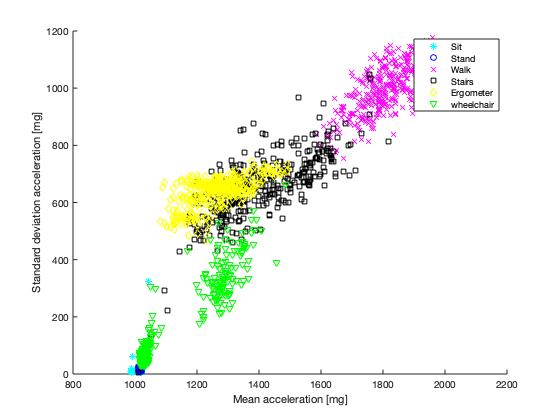


figure

hold on 
for i=1:length(colors)

scatter(Features.Mean_Mean_Accel_Left_right(Features.Class==i,1),Features.Mean_Std_Accel_Left_right(Features.Class==i,1),(symbols(i)),(colors(i)))
hold on 
end 

legend("Sit", "Stand", "Walk", "Stairs", "Ergometer", "wheelchair")

xlabel('Mean acceleration [mg]')   
ylabel('Standard deviation acceleration [mg]' )

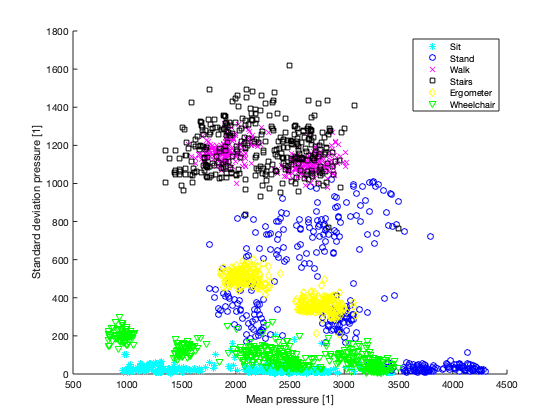

%set(gca, 'color', [0,0,1])



figure
for i=1:length(colors)

scatter(Features.Mean_Mean_Pressure_Left_right(Features.Class==i,1),Features.Mean_Std_Pressure_Left_right(Features.Class==i,1),(symbols(i)+colors(i)))
hold on 
end 

legend("Sit", "Stand", "Walk", "Stairs", "Ergometer", "Wheelchair")

xlabel('Mean pressure [1]')   
ylabel('Standard deviation pressure [1]' )


clf

